# Trabalho 5 - Projeto de controladores PID no domínio da frequência

## Nome: Luiza Batista Laquini

## Data limite para entrega: 24/11, 6h

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- O trabalho não é recebido por email.

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entregue no prazo o que estiver pronto.

I=21; % Seu valor de I
[G, ts0, G1]=ini_t5(I)

G =
 
            17
  ----------------------
  135.2 s^2 + 31.2 s + 1
 
Continuous-time transfer function.
Model Properties


ts0 = 35.5000

G1 =
 
  17
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


datetime('now')

ans = datetime
   24-Nov-2023 09:45:36


**Parte I: **Projete um controlador PI C1 que atenda:

- Erro nulo em regime para entrada degrau

- Tempo de estabelecimento $\le$ts0 segundos.

**Parte II: **Projete um controlador derivativo C2 de modo a obter um controlador PID=C1*C2 tal que as especificações anteriores sejam mantidas e adicionalmente se tenha

- Sobreelevação $\le$4%

- Tempo de estabelecimento menor que ts0

**Parte III: Estabilização: ** Usar critério de Nyquist para verificar se um controlador PD ou PI estabiliza G1(s)

**O que apresentar:**

Projeto do controlador PI (C1):

1) Gráfico de Bode de G e de C1G explicando a escolha do módulo adicionado, a localização do zero do PI, e as mudanças que o controlador C1 ocasionou nas margens de ganho e fase. Identifique a frequência de cruzamento de ganho por 0dB no gráfico de Bode com o controlador C1.

2) Resposta ao degrau em malha fechada e sinal de controle aplicado plotados no mesmo gráfico, mostrando o atendimento das especificações e explicitando os valores de Kp e Ki.

3) Resumir os passos do projeto do controlador PI (**Atenção: não são os comandos dados!**) 

Projeto do controlador PD (C2):

4) Gráfico de Bode de C1G e de C1C2G identificando a localização do zero do PD, e as mudanças que o controlador C2 ocasionou na margem de fase em relação ao controlador C1G.

5) Resposta ao degrau em malha fechada mostrando o atendimento das especificações.

6) Sinal de controle devido ao controlador C1C2, explicitando o valor de Kd e o parâmetro Tf do filtro.

7) Resumir os passos do projeto do PD  (**Atenção: não são os comandos dados!**)

Estabilização:

8) Verifique via critério de Nyquist se um controlador PD estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério

9) Verifique via critério de Nyquist se um controlador PI estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério

## **Parte I: Projeto do PI (C1) **

FT G(s):

G

G =
 
            17
  ----------------------
  135.2 s^2 + 31.2 s + 1
 
Continuous-time transfer function.
Model Properties


As especificações de projeto são:

- Erro nulo em regime para entrada degrau

- Tempo de estabelecimento $\le$ts0 segundos.

Vamos visualizar como está a resposta ao degrau para a FT de G: 

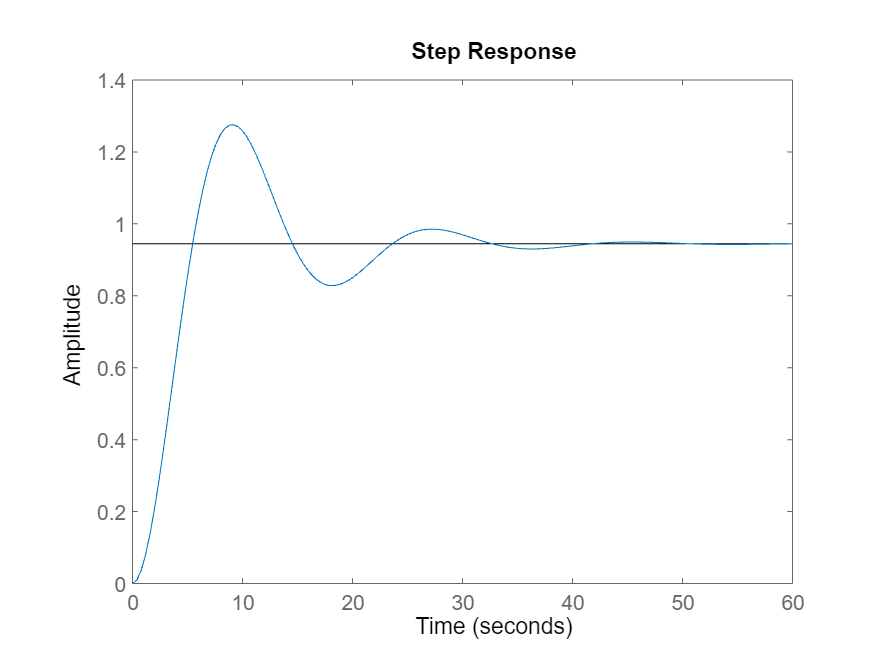

T = feedback(G, 1); % fecha a malha
step(T) % degrau

stepinfo(T)

ans = struct with fields:
         RiseTime: 3.6913
    TransientTime: 30.6447
     SettlingTime: 30.6447
      SettlingMin: 0.8284
      SettlingMax: 1.2756
        Overshoot: 35.0670
       Undershoot: 0
             Peak: 1.2756
         PeakTime: 9.1796


Observações tiradas da resposta ao degrau:

- Estabilização em aprox. 0.95

- Erro de aprox. 0.05

- Tempo de estabelecimento inicialmente está sendo atendido (30.6447 < 35.5)

Agora, visualizando o gráfico de Bode para G:

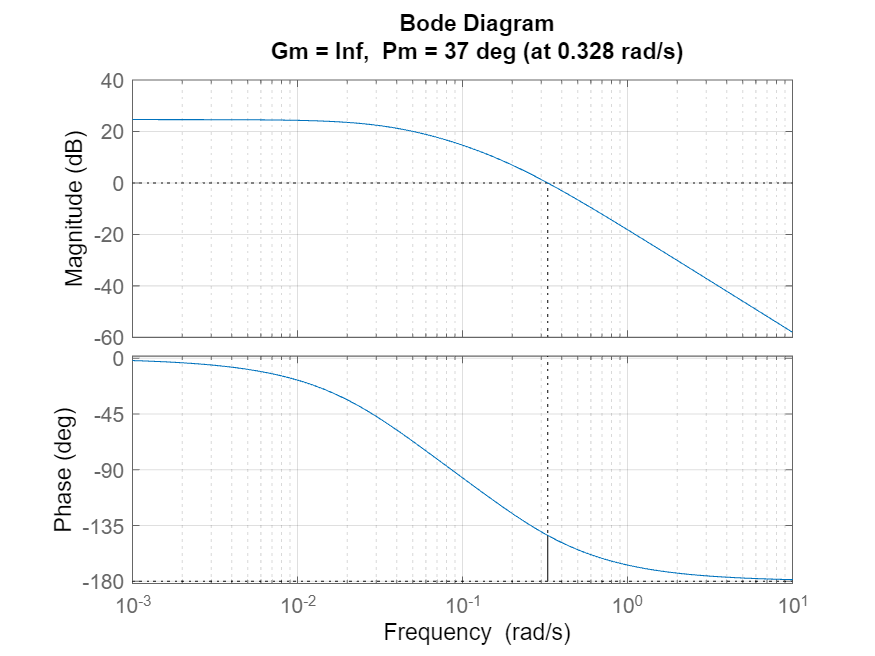

margin(G)
grid on

Observações tiradas do Gráfico de Bode:

- MF = 37

- MG = inf.

- $\omega g=$ 0.328

- Não há polos ou zeros na origem, pois a fase se inicia em 0.

O controlador PI adiciona um polo na origem que vai aumentar o tipo do sistema (de tipo zero para tipo um) e vai garantir o erro nulo à entrada degrau. Porém isso também pode mexer com o tempo de estabelecimento. Vamos usar a função rltool apenas para confirmar se isso ocorrerá por meio da visualização da resposta e do gráfico de Bode:

%rltool(G)

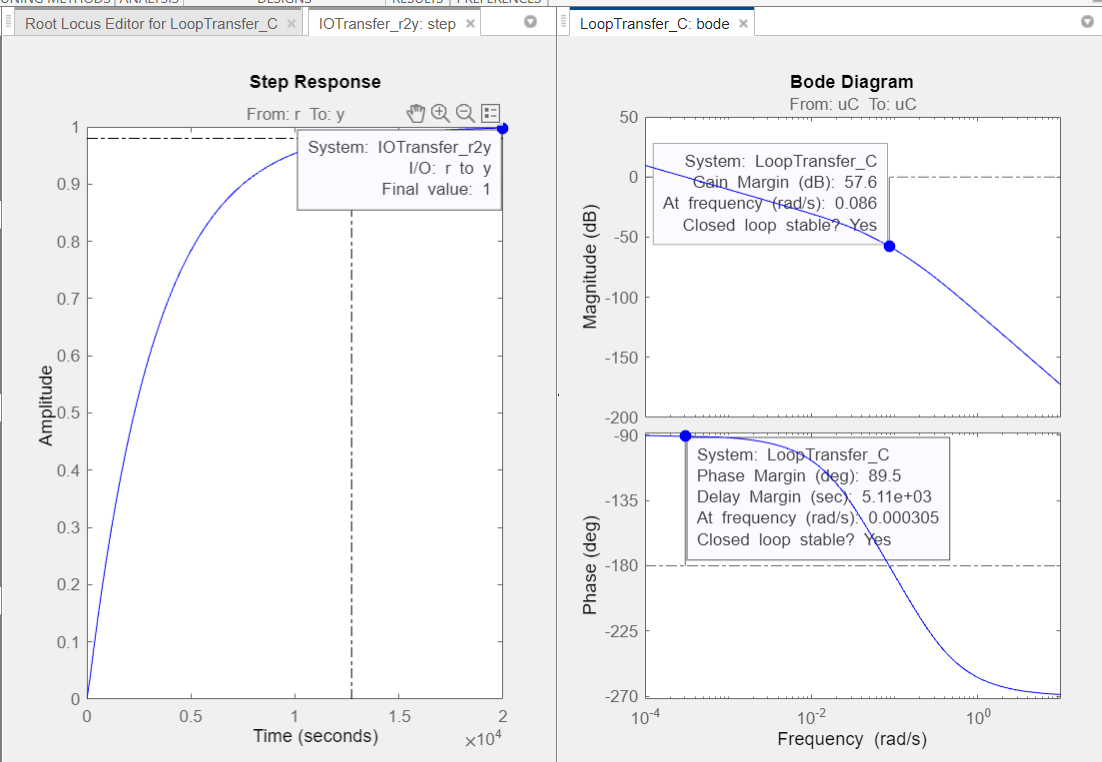

Como esperado, a adição de um polo integrador zerou o erro, mas aumentou muito o tempo de estabelecimento.

Portanto, agora garantimos o erro nulo, mas a condição de transitório ainda deve ser atendida.

Ao projetar no domínio da frequência, a margem de fase passa a ser a especificação relacionada ao transitório a ser atendida, sendo verificada no gráfico de Bode. A margem de fase está relacionada ao amortecimento e à sobreelevação no domínio do tempo.

Vamos ao projeto do PI pelo gráfico de Bode:

Se o módulo de G cruzasse 0dB em uma frequência um pouco mais baixa (chamamos de $\omega_g^{'}$), a MF seria maior. Para que isto aconteça, basta escolher $K_p<1$ para abaixar a curva de módulo. Assim, escolhendo $K_p$ tal que $|G(j\omega_g^{'})|+20log_{10}K_p=0$ ou $K_p=10^{-\frac{|G(j\omega_g^{'})|}{20}}$ , o módulo da curva compensada cruzará em 0dB na nova freqüência $\omega_g^{'}$.

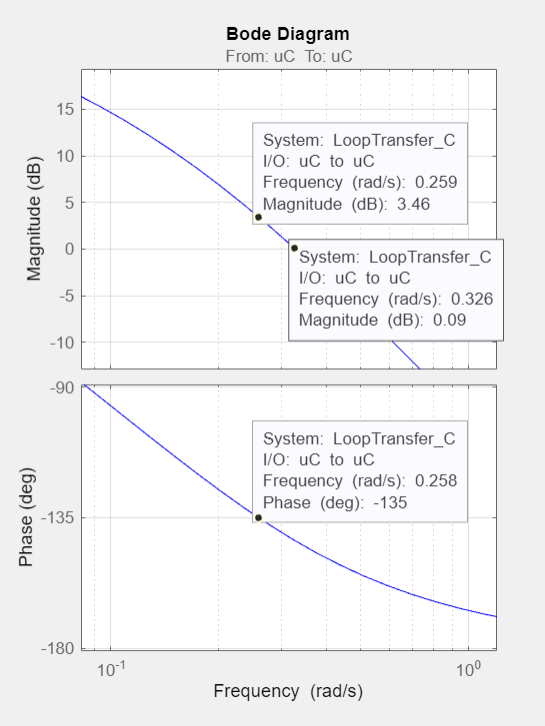 

A margem de fase é 37 graus. Suponha que se queira aumentar para 45 graus. Para isto, a curva de módulo deve cruzar por 0 dB em aproximadamente $\omega_g^{'}=0.26rad/s$, implicando em uma reducão do módulo de aproximadamente 3.46dB (valores podem ser conferidos conforme imagem acima). Usando a expressão $K_p=10^{-\frac{|G(j\omega_g^{'})|}{20}}$, $K_p=10^{-\frac{3.46}{20}}=0.67$		

O zero do PI em $s=-\frac{K_i}{K_p}$ deve ser colocado uma década antes de $\omega_g^{'}$, portanto em $0.067rad/s$, de modo que em $\omega=0.67rad/s$ o efeito do atraso de fase do controlador já tenha desaparecido. 

Falta agora obter o valor de $K_i$ usando:


$$\frac{K_i}{K_p}=\frac{\omega_g^{'}}{10}$$



$$\frac{K_i}{0.67}=\frac{0.26}{10}$$


Ki = 0.01742

Observando as modificações sobrepondo o gráfico de G e de G*C1:

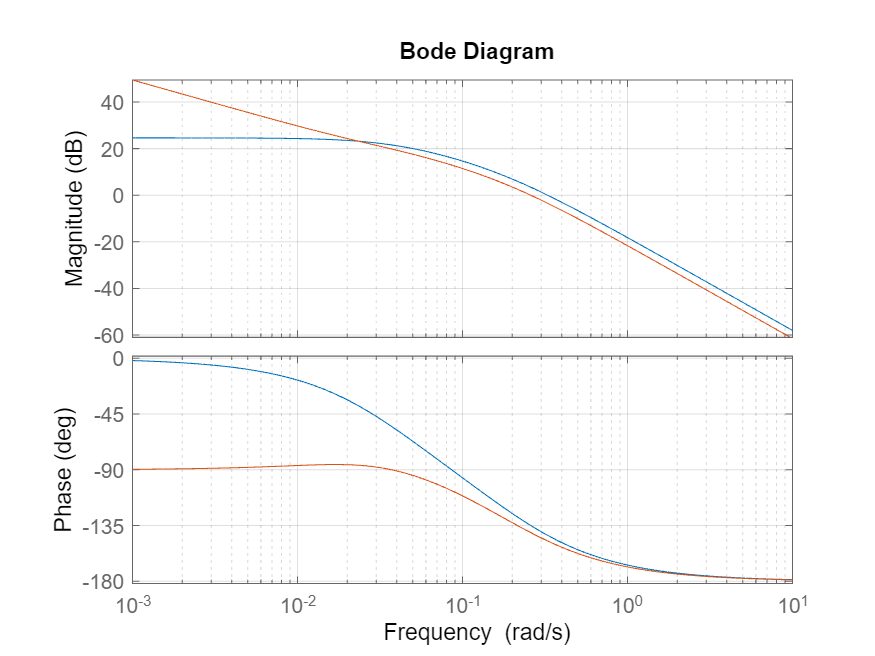

Kp=0.67;
Ki=0.01742;
C1=tf([Kp Ki],[1 0]);
bode(G,C1*G);grid;

Observa-se a diferença do módulo que diminuiu em frequências mais altas, o que indica melhor estabilidade. Além disso, há o efeito da adição do polo na origem sobre a fase, que antes começava em zero e passou a começar em -90º, zerando o erro à resposta degrau. Também há o efeito do zero adicionado, que contribui aumentando a fase em frequencias especificas, em torno da sua localização, o que aumenta a margem de fase do sistema, aumentando o amortecimento.

Agora, vamos verificar se as especificações de projeto foram atendidas visualizando a resposta ao degrau em malha fechada (antes x depois) e sinal de controle aplicado plotados no mesmo gráfico:

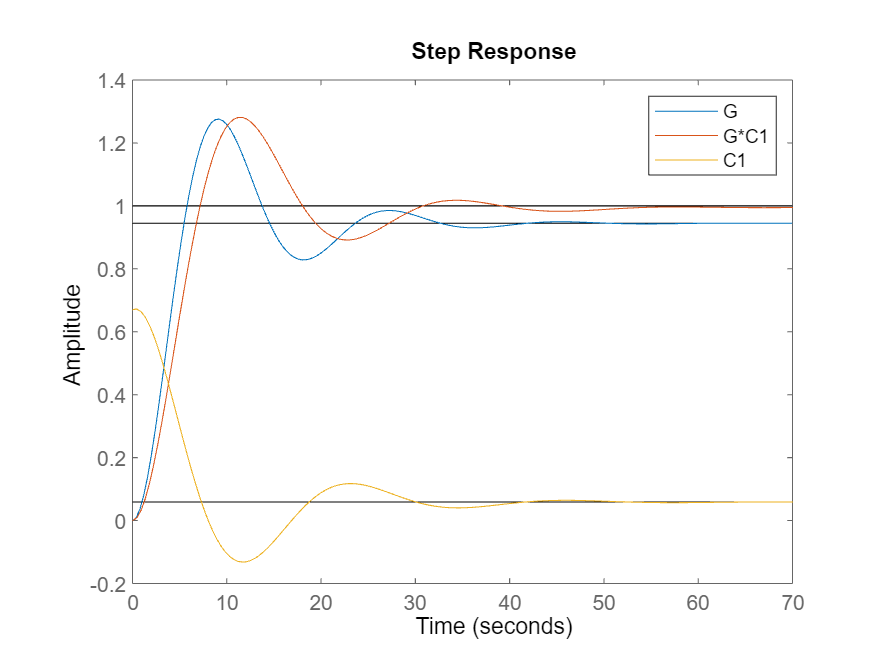

m=feedback(C1*G,1);
mu=feedback(C1,G);
figure;step(T,m,mu);legend('G', 'G*C1', 'C1')

Verificando o tempo de estabelecimento da FT após adição do controle PI:

stepinfo(m)

ans = struct with fields:
         RiseTime: 4.8513
    TransientTime: 29.3020
     SettlingTime: 29.3020
      SettlingMin: 0.8915
      SettlingMax: 1.2810
        Overshoot: 28.0965
       Undershoot: 0
             Peak: 1.2810
         PeakTime: 11.6571


O erro é nulo e o tempo de estabelecimento é de 29.3020s (<35.5s), ou seja, as especificações de projeto foram atendidas para **Kp = 0.67 e Ki = 0.01742. **Há um overshoot de 28.0965.

O projeto do controlador PI aqui realizado pode ser resumido da seguinte maneira:

- Verificação se o erro em regime era atendido

- Escolha da frequência de cruzamento de fase $\omega g$ para a qual se tem a Margem de Fase desejada

- Cálculo do ganho Kp para baixar a curva de módulo usando $\textrm{Kp}={10}^{-\frac{|G\left(j\omega g\right)|}{20}}$

- Cálculo do Ki fazendo $\frac{\textrm{Ki}}{\textrm{Kp}}=\frac{\omega g}{10}$

## Parte II: Projeto do PD (C2)

As especificações de projeto agora são:

- Sobreelevação $\le$4%

- Tempo de estabelecimento menor que ts0

Como visto na parte I com o projeto do PI, o controle obtido proporcionou uma resposta com overshoot de 28.0965, o que é > 4%. Portanto, com o projeto do controlador PD queremos aumentar a margem de fase para reduzir a sua oscilação, mas mantendo uma resposta rápida. A união desses dois projetos nos dará um controle PID.

O controlador PD adiciona um zero em $s=-\frac{\textrm{Kp}}{\textrm{Kd}}$

Assim, o ganho Kp deve ser escolhido para atender o erro em regime e o tempo de estabelecimento, e Kd para atender a condição de transitório, especificado em termos de margem de fase.

O controlador PID é obtido projetando primeiro o controlador PI e depois o controlador PD. O controlador PI deve garantir o erro em regime e bons tempos de resposta e o controlador PD é usado para reduzir a sobreelevação, aumentando a margem de fase, que pode aparecer devido aos valores maiores de Kp para obter respostas rápidas.

O que foi obtido com o controlador PI é dado no gráfico de bode a seguir:

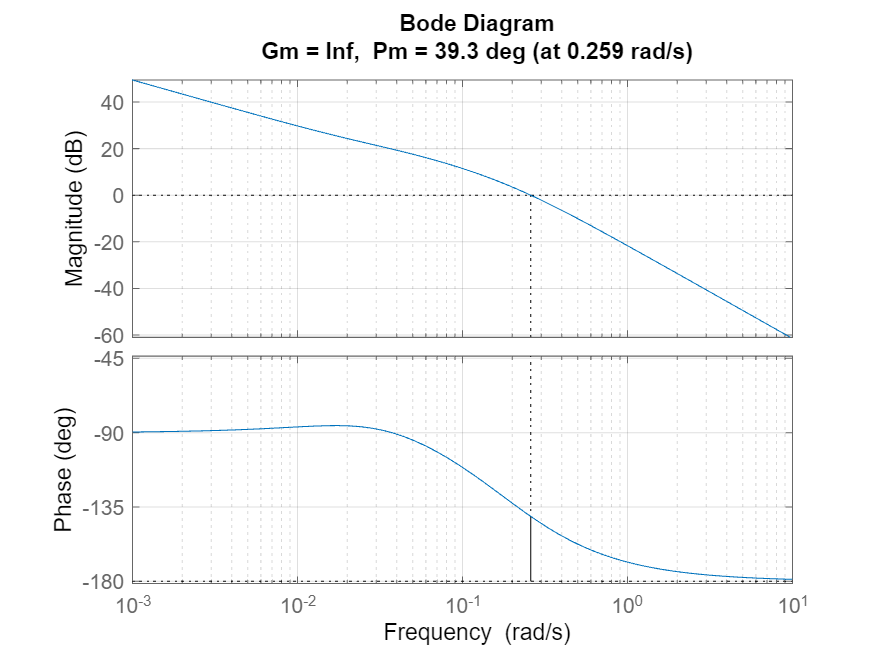

margin(G*C1);
grid on

Vê-se que a margem de fase é igual a 39.3º em 0.259 rad/s e isso nos dá aquela sobreelevação de 28.0965. Entretanto, o tempo de estabelecimento já foi atendido e o erro em regime também (garantidos com o PI). 

Seja então o controlador PID: 

A parte proporcional do controlador PD é feita igual a 1. (Kp=1)

Kp = 1;

Adicionando o zero do PD na frequência de corte $\omega g=0.259rad/s$

Dado que $\omega g=\frac{1}{\mathrm{Kd}}$

Então $0\ldotp 259=\frac{1}{\mathrm{Kd}}$

Kd = 1/0.259

Kd = 3.8610

Assim, temos o controlador PD:

C2 = tf([Kd Kp],1)

C2 =
 
  3.861 s + 1
 
Continuous-time transfer function.
Model Properties


E o controlador PID vai ser  a união do PI com o PD:

PID = C1*C2

PID =
 
  2.587 s^2 + 0.7373 s + 0.01742
  ------------------------------
                s
 
Continuous-time transfer function.
Model Properties


Vamos visualizar a resposta obtida pelo controlador PID:

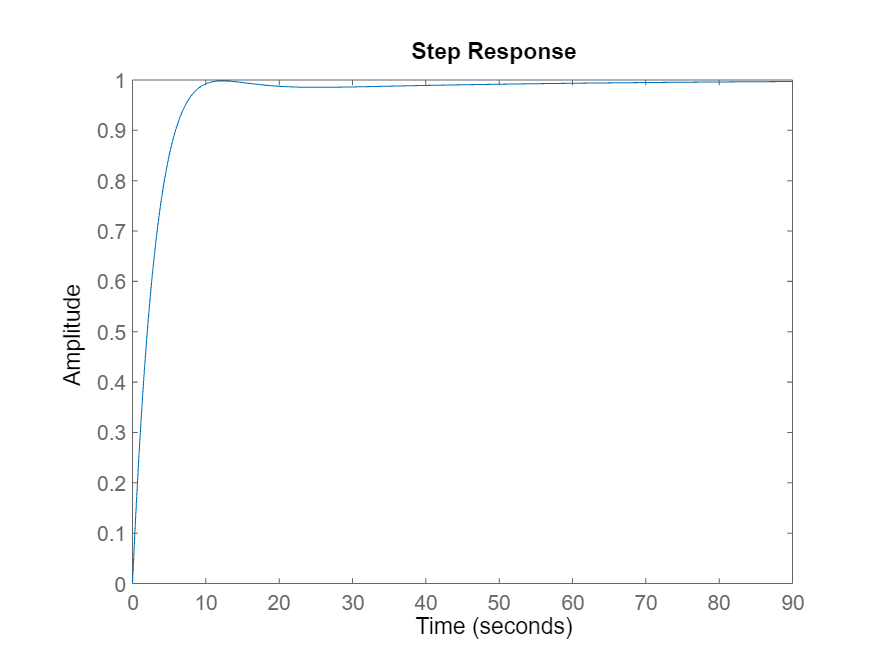

Mpid = feedback(PID*G,1);
step(Mpid)

stepinfo(Mpid)

ans = struct with fields:
         RiseTime: 5.5504
    TransientTime: 8.7069
     SettlingTime: 8.7069
      SettlingMin: 0.9014
      SettlingMax: 0.9982
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9982
         PeakTime: 12.3204


A nova sobreelevação é de zero, o tempo de estabelecimento melhorou (agora está em 8.7069s) e o erro permanece zerado (garantido pelo PI). Portanto, as especificações de projeto foram atendidas.

Visualizando o gráfico de Bode para PI comparado ao PID:

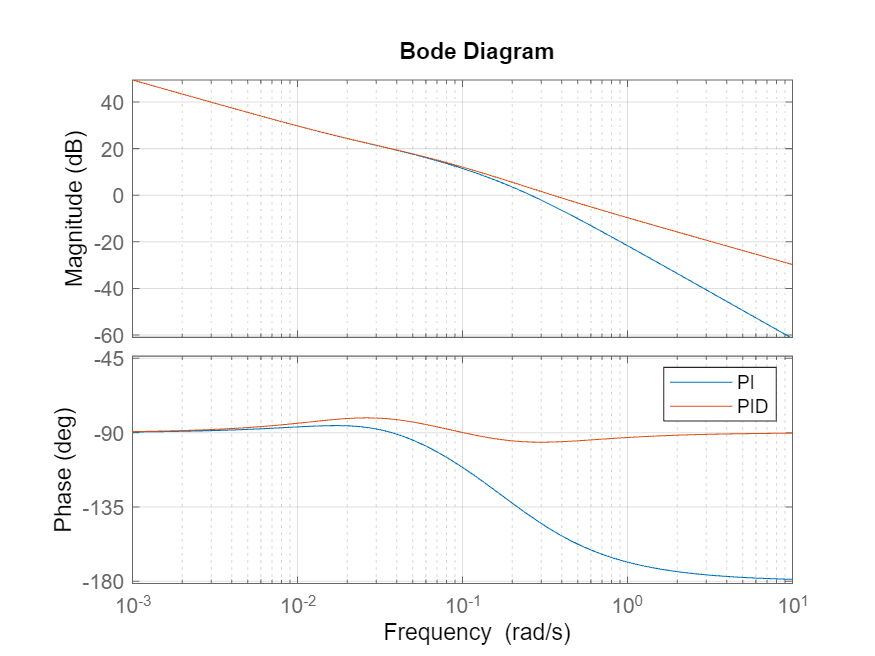

figure;
bode(C1*G,PID*G);grid;
legend('PI','PID')

Há um aumento de fase para o PID que foi objetivado com o projeto do PD. Além disso, há uma diminuição de módulo para frequências mais altas, comprovando a maior estabilidade. Observa-se também, o efeito o zero na frequência 0.259, que contribui aumentando a fase em seu entorno.

A função de transferência pro sinal de controle do PID será sempre não causal, não permitindo a simulação. A solução é usar um filtro na parte derivativa para permitir a visualização. No caso de implementar esse filtro no controle PD, fazemos:

 
$$G_c(s)=K_p+K_d\frac{s}{T_fs+1}$$


O parâmetro Tf atua como um filtro da parte derivativa, e deve ser escolhido de forma a não interferir no desempenho do controlador. O polo do filtro estará em s = -1/Tf . Logo, valores pequenos de Tf introduzem polos distantes da origem, afetando pouco o omportamento de C(s), mas tornando real a causalidade o que nos permite simular o sinal.

Portanto, vamos assumir Tf como um valor muito pequeno, como 0.0001. Chamando o controle PD com filtro de C2f, temos:

(Relembrando os valores de Kd = 3.8610 e Kp = 1)

Tf = 0.0001

Tf = 1.0000e-04

C2f = tf([Kd Kp], [Tf 1])

C2f =
 
  3.861 s + 1
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.
Model Properties


Assim o PID com o filtro no PD fica:

PIDf = C1*C2f

PIDf =
 
  2.587 s^2 + 0.7373 s + 0.01742
  ------------------------------
          0.0001 s^2 + s
 
Continuous-time transfer function.
Model Properties


Vamos comparar as respostas para garantir que o filtro nao está interferindo:

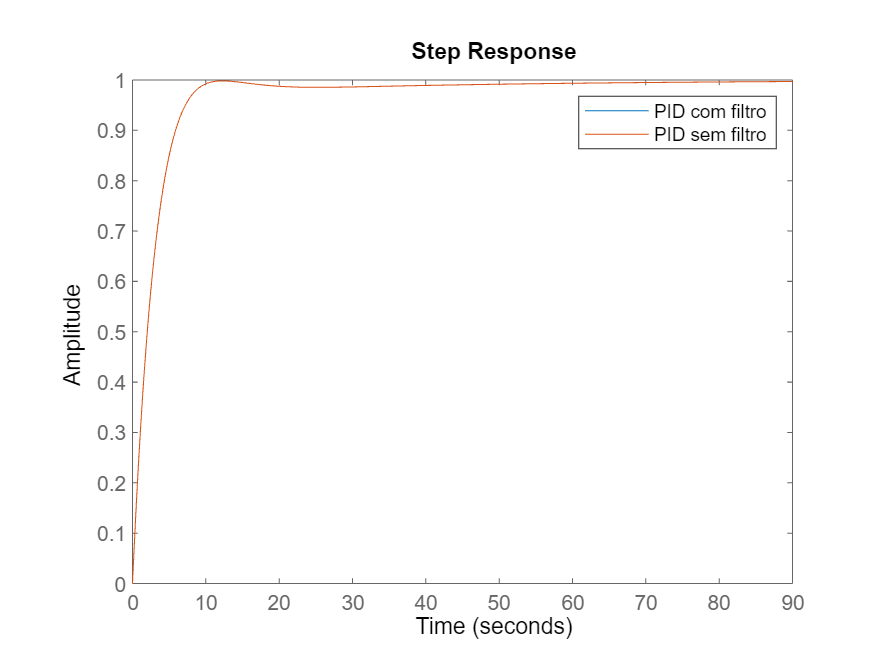

Mpidf = feedback(PIDf*G,1);
step(Mpidf, Mpid);legend('PID com filtro', 'PID sem filtro')

As respostas são extremamente semelhantes, portanto o filtro pode ser usado. Assim, podemos simular o sinal de controle:

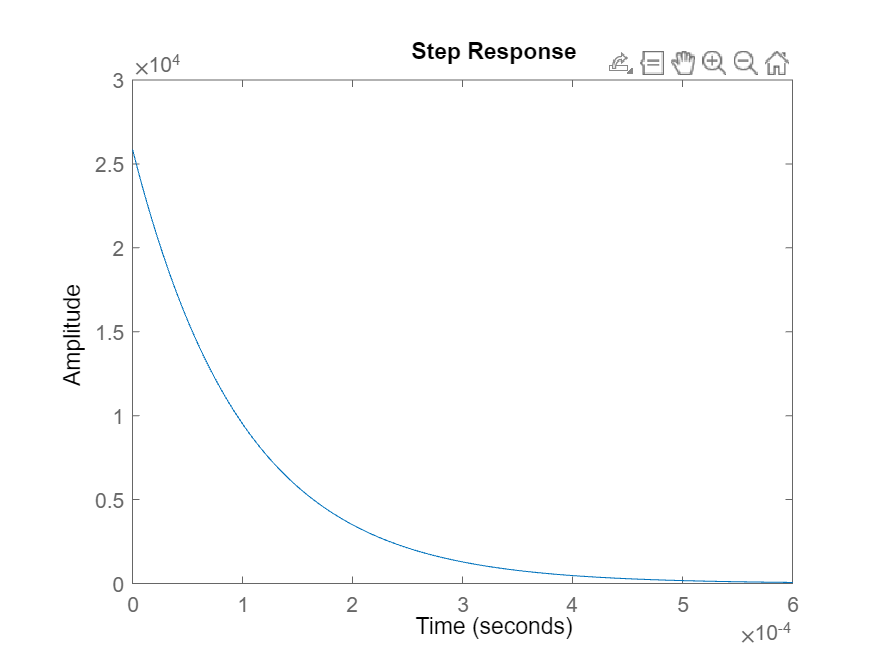

Mupidf = feedback(PIDf,G);
step(Mupidf)

Portanto, os passos para projeto do PD aqui empregados podem ser resumidos em:

- Verificação se o PD atendia o overshoot, o erro em regime e a margem de fase especificada;

- Escolha do ganho Kp

- Alocação do zero do PD

- Não foi necessário variar o zero, pois foram atendidas as especificações. 

## Parte III: Estabilização

Fazer os gráficos de Nyquist (à mão ou no Matlab) e aplicar o critério

Relembrando G1:

G1

G1 =
 
  17
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


**Critério de estabilidade de Nyquist**

Seja a FT $G(s)$e seu correspondente gráfico polar ou de Nyquist. 

O critério simplificado de Nyquist é dado por:

$\phi=(Z_d-P_d-\frac{P_\omega}{2})$*180º

Onde:

$\phi:$ângulo feito pelo gráfico polar em torno do ponto -1 quando $\omega$ varia de infinito a zero.

$P_d:$polos de G(s) no semi-plano direito 

$P_\omega:$polos de G(s) na origem

$Z_d:$polos de malha fechada no semi-plano direito ( é o que se quer saber)

Os 3 primeiros ($\phi,P_d,P_\omega$) são dados de malha aberta, enquanto $Z_d$ é um dado de malha fechada.

Para estabilidade, $\phi$ deve ser negativo ($Z_d=0$).

Dados de malha aberta: 

- Pd = 0

- Pw = 1

Para a estabilidade:

- Zd = 0

Portanto:


$$\phi=(Z_d-P_d-\frac{P_\omega}{2}).180º$$



$$\phi=(0-0-1).180º$$



$$\phi=-180º$$


Gráfico de Nyquist para G1:

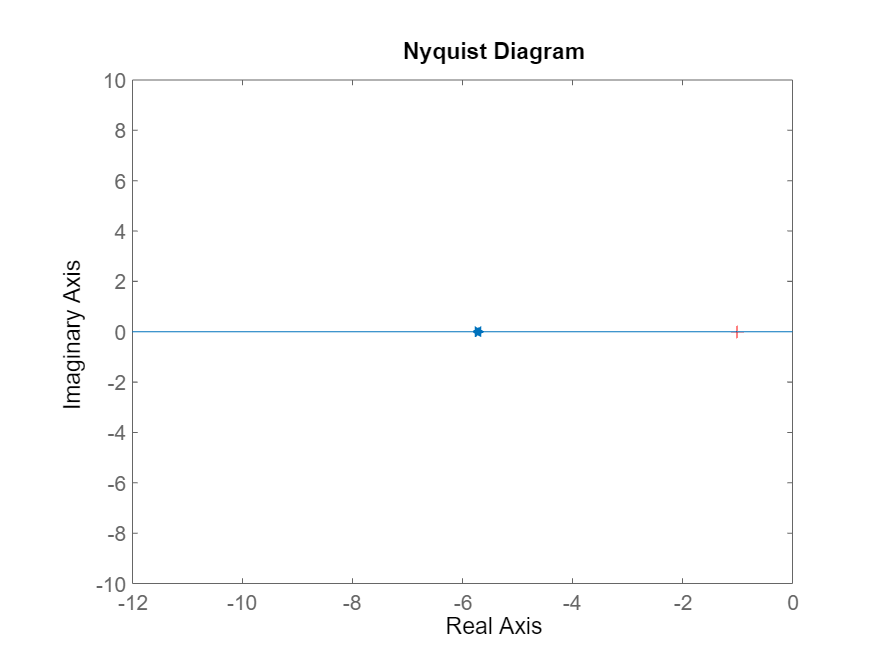

nyquist(G1)

Não é estável, pois $\phi=0º$ (diferente de 180º que calculamos para a estabilidade)

**Verifique via critério de Nyquist se um controlador PD estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério.**

Verificando se um controlador PD estabiliza G1:

Um controlador PD adiciona um zero na FT em s = -Kp/Kd (SPE), de forma que:

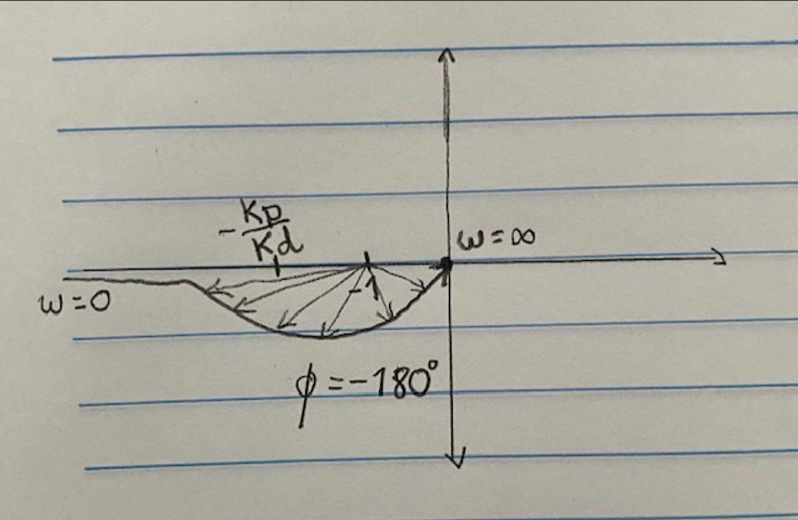

É possível afirmar que o PD estabiliza G1(s), pois independentemente da posição do zero no SPE este torna $\phi=-180º$

**Verifique via critério de Nyquist se um controlador PI estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério.**

Verificando se um controlador PI estabiliza G1:

Um controlador PI adiciona um polo na origem, que faz necessário refazer o critério de estabilidade:

Dados de malha aberta: 

- Pd = 0

- Pw = 3/2 = 1.5

Para a estabilidade:

- Zd = 0

Portanto:


$$\phi=(Z_d-P_d-\frac{P_\omega}{2}).180º$$



$$\phi=(0-0-1.5).180º$$



$$\phi=-270º$$


Um controlador PI também adiciona um zero em s = -Ki/Kp (SPE). De forma que:

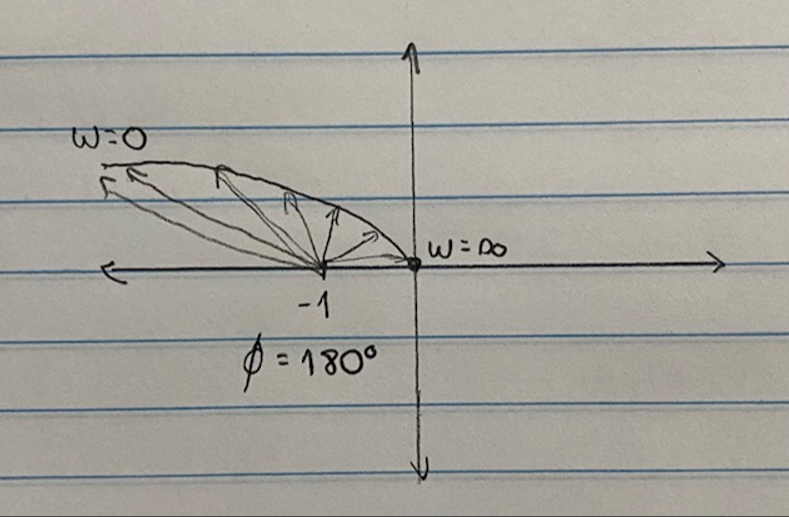

A posição do zero não interfere na posição dos fasores, já que todos os polos estão na origem. Assim, podemos afirmar que o sistema é instável ao utilizar um controlador PI, já que $\phi=-270º$ não é atendido, pois $\phi=180º$.

Conclui-se portanto que PD estabiliza G1(s) e PI não.